[target, ref] = recorded_samples();

cutoff = 400;
fs = 48000;

% target = highpass(target, cutoff, fs);
% ref = highpass(ref, cutoff, fs);


step_sizes = [.001, .005, .01, .05, .1, .5, .9];
ir_lens = [128, 256, 512, 1024];

N = length(ir_lens);
S = length(step_sizes);
n_iter = 20;
mses = zeros(N, S, n_iter);
preds = zeros(N, S, length(target));
factors = zeros(N, 1);

out_wav = zeros(N, S, length(target));

panel_ir = clipped_irs(128, 2);
best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);

    % panel_ir = highpass(panel_ir, cutoff, fs);

    [ref, factor, target, panel_ir] = normalize_data(ref, target, panel_ir);


    filter_order = ir_len * 2;

    for j = 1:length(step_sizes)
    
        step_size = step_sizes(j);
    
        fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
        fxlms.gpu = false;
        [pred_i, mses_i] = fxlms.learn(n_iter);
    
        mses(i, j, :) = mses_i;
        preds(i, j, :) = denormalize_data(pred_i, factor);
        out_wav(i, j, :) = denormalize_data(fxlms.ref_filt, factor);
        
        disp(mses_i)

        if mses_i(end) < min_mse
            min_mse = mses_i(end);
            min_i = i;
            min_j = j;
            
            best_filt = fxlms;
        end
    end

    [ref, target, panel_ir] = denormalize_data(ref, factor, target, panel_ir);
    factors(i) = factor;

    disp('');

end

   1.0e-04 *

    0.1544    0.1150    0.1076    0.1039    0.1018    0.1005    0.0996    0.0990    0.0986    0.0983    0.0981    0.0980    0.0978    0.0977    0.0976    0.0976    0.0975    0.0975    0.0974    0.0974

   1.0e-04 *

    0.1003    0.0820    0.0806    0.0802    0.0800    0.0799    0.0798    0.0798    0.0797    0.0797    0.0797    0.0796    0.0796    0.0796    0.0796    0.0795    0.0795    0.0795    0.0795    0.0795

   1.0e-05 *

    0.7914    0.6894    0.6856    0.6845    0.6838    0.6833    0.6830    0.6828    0.6826    0.6824    0.6823    0.6821    0.6820    0.6820    0.6819    0.6818    0.6817    0.6817    0.6816    0.6815

   1.0e-05 *

    0.3869    0.3664    0.3665    0.3666    0.3667    0.3668    0.3669    0.3670    0.3671    0.3672    0.3672    0.3673    0.3674    0.3674    0.3675    0.3676    0.3676    0.3677    0.3677    0.3678

   1.0e-05 *

    0.2429    0.2351    0.2354    0.2356    0.2358    0.2360    0.2361    0.2362    0.2364    0.2365    0.2366    0.2367  

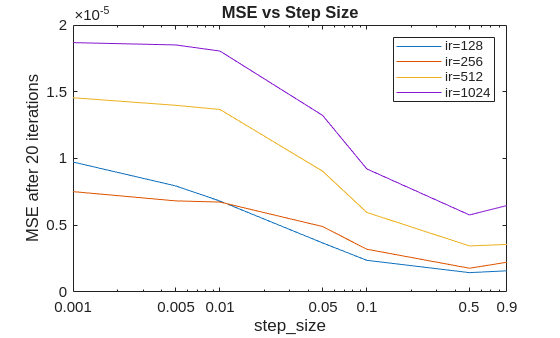

figure
plot(step_sizes, mses(1, :, end))
hold on
plot(step_sizes, mses(2, :, end))
hold on
plot(step_sizes, mses(3, :, end))
hold on
plot(step_sizes, mses(4, :, end))
set(gca, 'XScale', 'log')
xlim([step_sizes(1), step_sizes(end)])
xticks(step_sizes)

legend("ir=128", "ir=256", "ir=512", "ir=1024")
xlabel("step\_size")
ylabel("MSE after 20 iterations")
title("MSE vs Step Size")

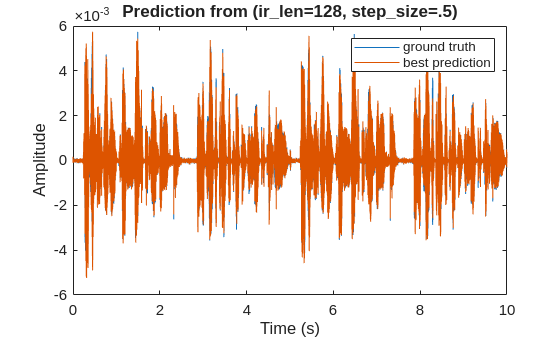

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, squeeze(preds(min_i, min_j, :)));
legend("ground truth", "best prediction")

title("Prediction from (ir\_len=128, step\_size=.5)")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

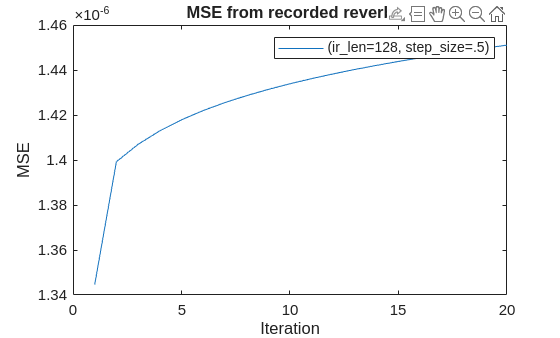

figure
plot(squeeze(mses(min_i, min_j, :)))
title('MSE from recorded reverb')
xlabel('Iteration')
ylabel('MSE')
legend('(ir\_len=128, step\_size=.5)')

min_i % ir_length

min_i = 1

min_j % step size

min_j = 6

function save_cancel_clip(wav, filename)
    [a, fs] = arthur();
    wav = wav(1:length(a));

    disp(size(a))
    disp(size(wav))
    
    y = ([wav, a]);

    audiowrite([filename, '.wav'], y, fs);
    audiowrite([filename, '_no_cancel.wav'], [zeros(length(a), 1), a], fs);
end

% 
% for i = 1:N
%     save_cancel_clip(squeeze(out_wav(i, min_j, :)), sprintf('fxlms_norm_ir=%d', ir_lens(i)));
% end

% 

% c = CancelAnalysis('fxlms');

% c.plot_cancel_results()
